# **Visión Artificial. GIEC.**

# **	Sistemas de Visión Artificial. GIC.**

**	Miguel Ángel García, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Autor(es):Paula Fernández Sánchez, Luis Ramos Triguero, María Díez Martínez**

**Fecha:16-10-2026**

El objetivo principal de esta práctica es familiarizarse con los principales operadores morfológicos y analizar el efecto que producen el **tipo, la forma y el tamaño del elemento estructurante** sobre distintos tipos de imágenes.

close all
clear all

1) Lea la imagen en color 'autumn.tif' y muéstrela.

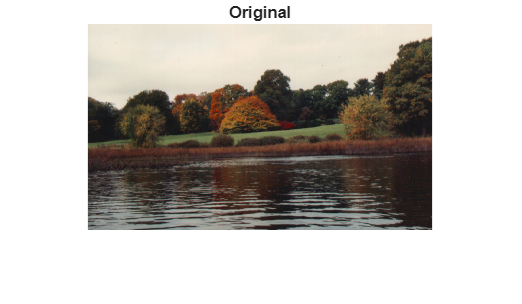

I = imread('autumn.tif');
figure
imshow(I);
title('Original');

2) Utilizando la función strel, cree un elemento estructurante con forma de disco de 5 píxeles de radio. 

 se = strel('disk', 5);

3) Erosione y dilate la imagen utilizando dicho elemento estructurante y muestre conjuntamente la imagen original y las dos imágenes resultantes. Tenga en cuenta que, en una imagen RGB, MATLAB aplica estas operaciones de forma independiente a cada una de las tres componentes de color.

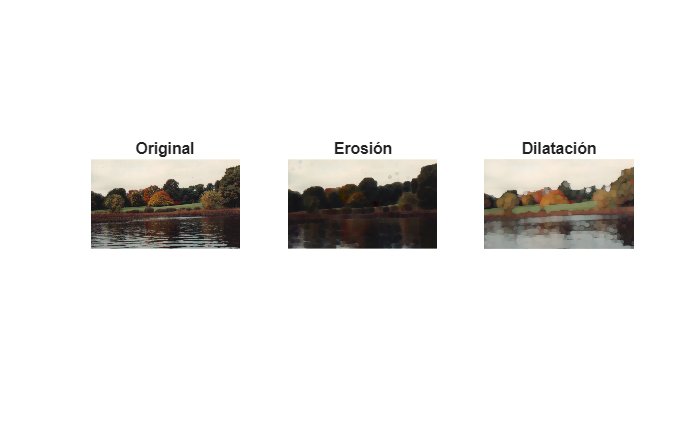

Ie = imerode(I, se);
Id = imdilate(I, se);

figure
subplot(1,3,1)
imshow(I);
title('Original');
subplot(1,3,2)
imshow(Ie);
title('Erosión');
subplot(1,3,3)
imshow(Id);
title('Dilatación');

Además, se pide: 

- Ejecute el programa cargando la imagen en escala de grises `'rice.png' `y  la imagen binaria `'circles.png'`. Observe el comportamiento de los operadores morfológicos sobre los distintos tipos de imágenes.¿Qué diferencias ve?

JUSTIFICACION: Los granos claros adelgazan con la erosión y engordan con la dilatación, y la imagen entera se oscurece con la erosion y se aclara con la dilatación.También observamos que en los circulos solo hay blanco y negro, así que el efecto es solo de forma: los círculos encogen o crecen y sus bordes toman la forma del disco.

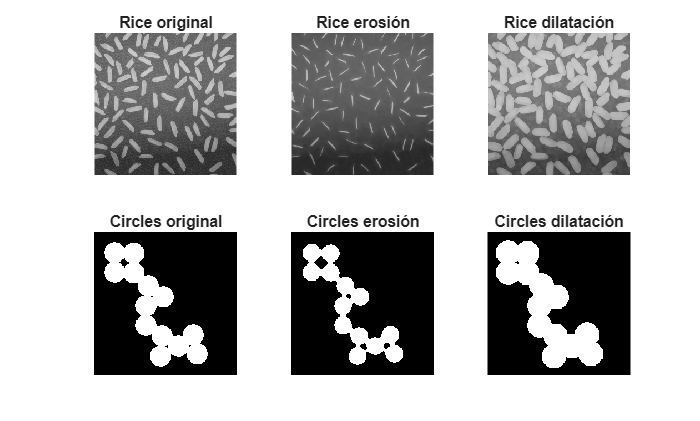

R = imread('rice.png');
Re = imerode(R, se);
Rd = imdilate(R, se);

C = imread('circles.png');
Ce = imerode(C, se);
Cd = imdilate(C, se);

figure
subplot(2,3,1)
imshow(R);
title('Rice original');
subplot(2,3,2)
imshow(Re);
title('Rice erosión');
subplot(2,3,3)
imshow(Rd);
title('Rice dilatación');
subplot(2,3,4)
imshow(C);
title('Circles original');
subplot(2,3,5)
imshow(Ce);
title('Circles erosión');
subplot(2,3,6)
imshow(Cd);
title('Circles dilatación');

2. Elementos estructurantes. Observe el efecto de las operaciones morfológicas utilizadas en (3) con elementos estructurantes de diferentes formas y tamaños (ver ayuda: [https://es.mathworks.com/help/images/ref/strel.html?s_tid=doc_ta).](https://es.mathworks.com/help/images/ref/strel.html?s_tid=doc_ta).)

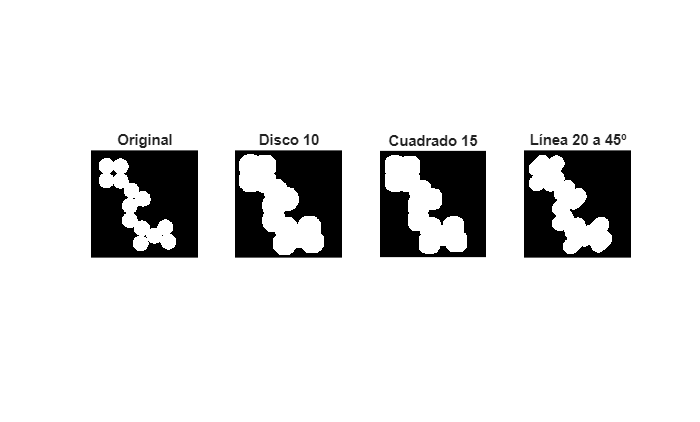

se1 = strel('disk', 10);
se2 = strel('square', 15);
se3 = strel('line', 20, 45);

C1 = imdilate(C, se1);
C2 = imdilate(C, se2);
C3 = imdilate(C, se3);

figure
subplot(1,4,1)
imshow(C);
title('Original');
subplot(1,4,2)
imshow(C1);
title('Disco 10');
subplot(1,4,3)
imshow(C2);
title('Cuadrado 15');
subplot(1,4,4)
imshow(C3);
title('Línea 20 a 45º');

3. Operadores morfológicos. Cargue la imagen en escala de grises `'rice.png' `y realice una operación de umbralizado con la función `imbinarize`, que por defecto utiliza el método de Otsu. Utilice las funciones `imclose` o `imopen` para eliminar los pequeños píxeles aislados que puedan estar en el fondo de la imagen. Tenga en cuenta que el tipo y tamaño del elemento estructurante debe ser ajustado.

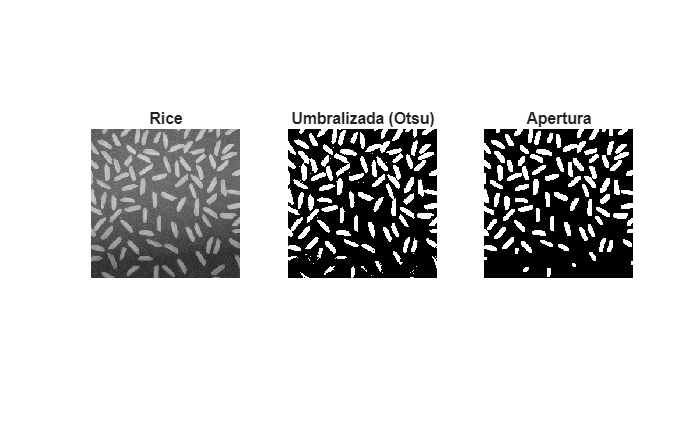

BW = imbinarize(R);
seA = strel('disk', 3);
BWa = imopen(BW, seA);

figure
subplot(1,3,1)
imshow(R);
title('Rice');
subplot(1,3,2)
imshow(BW);
title('Umbralizada (Otsu)');
subplot(1,3,3)
imshow(BWa);
title('Apertura');

4. Repita la pregunta anterior pero utilizando la imagen original complementada (utilice la función `imcomplement`).

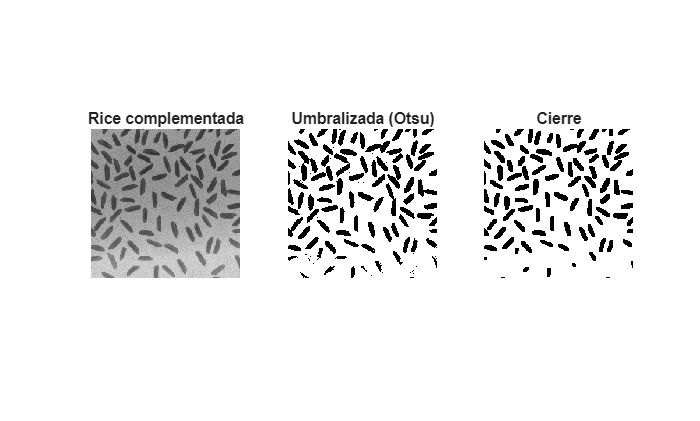

Rc = imcomplement(R);
BWc = imbinarize(Rc);
BWcc = imclose(BWc, seA);

figure
subplot(1,3,1)
imshow(Rc);
title('Rice complementada');
subplot(1,3,2)
imshow(BWc);
title('Umbralizada (Otsu)');
subplot(1,3,3)
imshow(BWcc);
title('Cierre');

5. Comente las diferencias en el efecto sobre los detalles en la imagen original y en la complementada.

JUSTIFICACION: Las principales diferencias son que en la imagen original, los detalles que se quieren eliminar son pequeños y claros sobre fondo oscuro, que se eliminan con una apertura. En la imagen complementada, esos mismos detalles son pequeños y oscuros sobre fondo claro, por lo que creemos tenemos que usar cierre. 

Dada la imagen "HuellaOrig.jpg", que presenta ruido (tanto puntos negros dentro de la huella, como puntos blancos por fuera), se pide:

- Crear una imagen en la que se hayan eliminado los puntos blancos de ruido,

- A partir de dicha imagen, eliminar también los puntos negros dentro de la huella, para generar una imagen limpia. 

- Elegir y justificar el tipo y tamaño del elemento estructurante y las operaciones morfológicas utilizadas.

JUSTIFICACIÓN: En cuanto a las operaciones, hemos hecho apertura primero, porque elimina los píxeles claros aislados, y luego cierre, porque rellena los huecos oscuros pequeños.Y en cuanto al elemento estructurante: hemos usado un disco, porque las líneas de la huella son curvas y tienen todas las orientaciones, así que no favorece ninguna dirección.

- Mostrar conjuntamente:

- imagen original; 

- resultado después de eliminar los puntos blancos; 

- resultado final después de eliminar también los puntos negros.

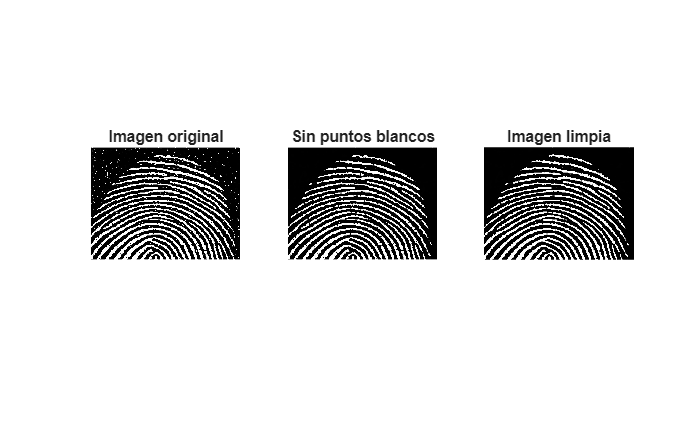

clear all
close all
se = strel('disk', 4);
original = imread('HuellaOrig.jpg');
sinBlancos = imopen(original, se);
limpia = imclose(sinBlancos, se);

figure
subplot(1,3,1)
imshow(original);
title('Imagen original');
subplot(1,3,2)
imshow(sinBlancos);
title('Sin puntos blancos');
subplot(1,3,3)
imshow(limpia);
title('Imagen limpia');

Dado el siguiente código:

% close all
% clear all

Step 1) Reading the Image

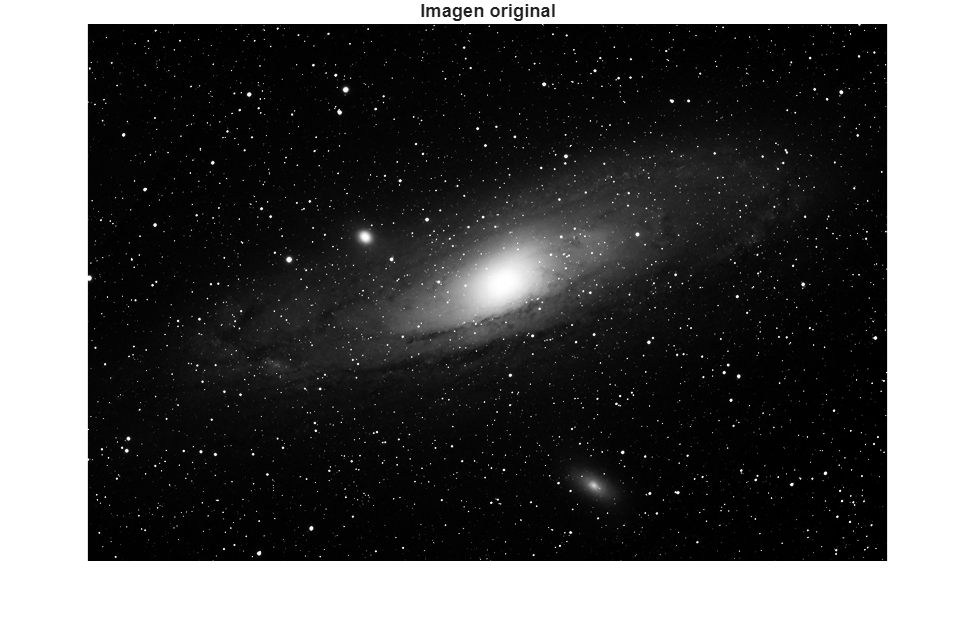

original = imread('galaxy.png');
figure;
imshow(original);
title('Imagen original');

Step 2) Creating a structuring element.

se = strel('disk',50);

Step 3) Top or Bottom Hat.

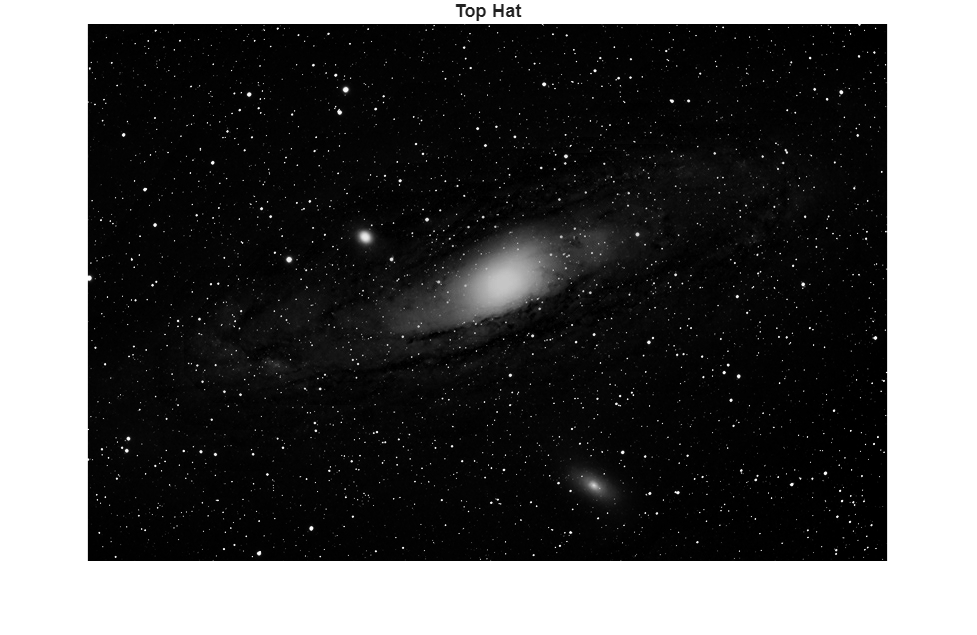

tophat = imtophat(original,se);
figure;
imshow(tophat);
title('Top Hat');

Se pide: 

- Suponga que solo interesan las estrellas pequeñas y que se desea eliminar la contribución de la galaxia. Las estrellas presentan tamaños del orden de unos pocos píxeles (aproximadamente 2–6 píxeles de radio), mientras que la galaxia presenta dimensiones muy superiores. Pruebe distintos radios para un elemento estructurante en forma de disco y determine experimentalmente un tamaño que permita conservar las estrellas pequeñas y eliminar la galaxia.

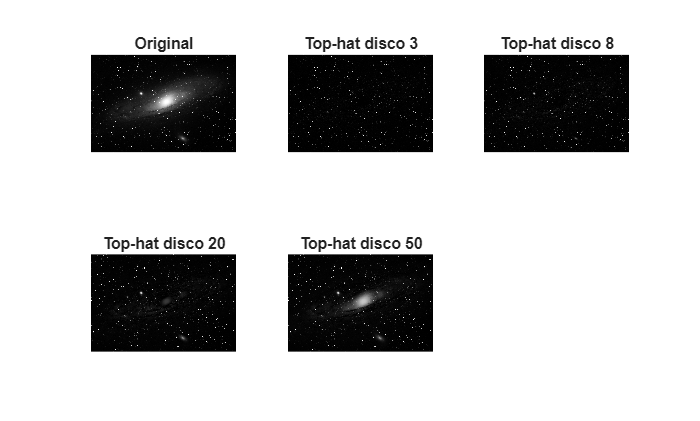

original = imread('galaxy.png');

th3 = imtophat(original, strel('disk', 3));
th8 = imtophat(original, strel('disk', 8));
th20 = imtophat(original, strel('disk', 20));
th50 = imtophat(original, strel('disk', 50));

figure
subplot(2,3,1)
imshow(original);
title('Original');
subplot(2,3,2)
imshow(th3);
title('Top-hat disco 3');
subplot(2,3,3)
imshow(th8);
title('Top-hat disco 8');
subplot(2,3,4)
imshow(th20);
title('Top-hat disco 20');
subplot(2,3,5)
imshow(th50);
title('Top-hat disco 50');

2. Cuando el fondo es blanco y el primer plano es oscuro, debemos cambiar el enfoque. Obtenga la imagen complementada con la función `imcomplement. `Aplique sobre ella la transformación *white top-hat* utilizada anteriormente y observe el resultado. ¿Por qué deja de ser adecuada esta operación para extraer las estrellas? Determine qué operación morfológica resulta ahora apropiada para extraer estructuras pequeñas más oscuras que su entorno, aplíquela y muestre el resultado.

JUSTIFICACION: Por qué el top-hat solo extrae estructuras pequeñas más claras que su entorno. En la imagen complementada las estrellas son más oscuras que el fondo, así que el top-hat ya no las encuentra y el resultado sale casi vacío. Creemos que es mas adecuado usar el bottom-hat, que extrae estructuras pequeñas y oscuras. Con el mismo disco de radio 8, las estrellas vuelven a aparecer (como puntos claros en el resultado) y la galaxia desaparece.

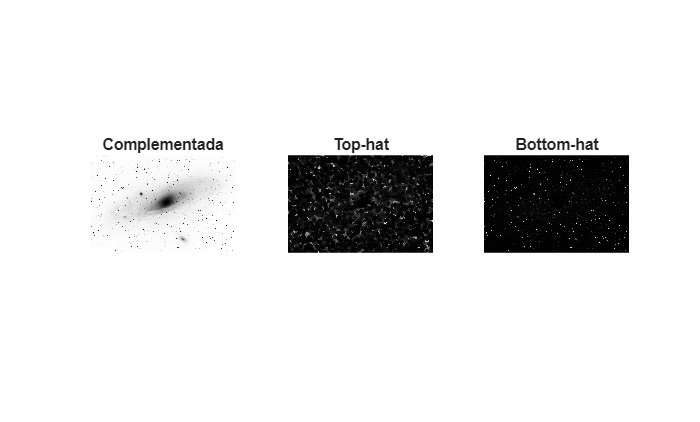

se = strel('disk', 8);
comp = imcomplement(original);

thComp = imtophat(comp, se);
bhComp = imbothat(comp, se);

figure
subplot(1,3,1)
imshow(comp);
title('Complementada');
subplot(1,3,2)
imshow(thComp);
title('Top-hat');
subplot(1,3,3)
imshow(bhComp);
title('Bottom-hat');